# Conversions

inch2m = 1/39.37;
bar2Pa = 100000;

# Task 1.1: Theoretical Mach number variation along working section 

## Interpolating the wind tunnel liner dimensions

Interpolation is necessary to align the points on both sections of the aerofoil. Later calculations will require consistent, matching point numbering. The values will also be converted to SI units from Imperial units.

topSurface_inches = readtable("Work\aerofoil-surface-dimensions.xlsx","Sheet","Top Surface")

topSurface_inches = 54×2 table
    x__inches_    y__1___inches_
    __________    ______________

          0            0.42     
       0.29           0.576     
       0.67           0.782     
      1.055           0.985     
       1.44           1.175     
       1.82           1.357     
      2.205           1.535     
       2.59           1.706     
      2.975           1.862     
      3.355           2.001     
       3.74           2.122     
      4.125            2.22     
       4.51           2.299     
       4.89           2.363     
      5.275           2.414     
       5.66           2.454     


bottomSurface_inches = readtable("Work\aerofoil-surface-dimensions.xlsx",Sheet="Bottom Surface")

bottomSurface_inches = 21×2 table
    x__inches_    y__2___inches_
    __________    ______________

          0            0.42     
      0.125           0.485     
       0.25           0.546     
      0.375           0.602     
        0.5           0.653     
      0.625           0.701     
       0.75           0.745     
      0.875           0.786     
          1           0.822     
      1.125           0.855     
       1.25           0.884     
      1.375            0.91     
        1.5           0.933     
      1.625           0.952     
       1.75           0.968     
      1.875           0.981     



topSurfaceArray_inches = table2array(topSurface_inches);
bottomSurfaceArray_inches = table2array(bottomSurface_inches);

% Inerpolating the bottom surface's y-coordinate points relative to the top surface's x-coordinates.
bottom_interp = interp1(bottomSurfaceArray_inches(:,1),bottomSurfaceArray_inches(:,2),topSurfaceArray_inches(:,1),"linear");

% Assembling the completed array, in inches
bottomSurfaceInterp_inches = [topSurfaceArray_inches(:,1) bottom_interp];

% Converting all matrices to S.I. units
bottomSurface = bottomSurfaceInterp_inches*inch2m;
topSurface = topSurfaceArray_inches*inch2m;

% Creating tables
bottomSurafce_table = array2table(bottomSurface);
bottomSurafce_table.Properties.VariableNames = {'x_metres' 'y_metres'};
topSurface_table = array2table(topSurface);
topSurface_table.Properties.VariableNames = {'x_metres' 'y_metres'};
bottomSurafce_table

bottomSurafce_table = 54×2 table
    x_metres    y_metres
    ________    ________

           0    0.010668
    0.007366    0.014324
    0.017018    0.018208
    0.026797    0.021248
    0.036576    0.023418
    0.046228    0.024772
    0.056007    0.025363
    0.065786      0.0254
    0.075565      0.0254
    0.085217      0.0254
    0.094996      0.0254
     0.10478      0.0254
     0.11455      0.0254
     0.12421      0.0254
     0.13399      0.0254
     0.14376      0.0254


topSurface_table

topSurface_table = 54×2 table
    x_metres    y_metres
    ________    ________

           0    0.010668
    0.007366     0.01463
    0.017018    0.019863
    0.026797    0.025019
    0.036576    0.029845
    0.046228    0.034468
    0.056007    0.038989
    0.065786    0.043332
    0.075565    0.047295
    0.085217    0.050826
    0.094996    0.053899
     0.10478    0.056388
     0.11455    0.058395
     0.12421     0.06002
     0.13399    0.061316
     0.14376    0.062332


## Plotting the Coordinates

Before plotting, the values must be corrected to show how they vary along the section. To do this, the centre of the wind tunnel(3 inches of its diameter) will be used as a reference point. The coordinates will then be added or subtracted to the constant 3, in order to show how the section varies. See the plot below for a better understanding of what this means.

% Finding the coordiantes of the top and bottom liners relative to the
% centre of the wind tunnel
bottomSurfacre_ycoord_relative = -3*inch2m + bottomSurface(:,2);
topSurface_ycoord_relative = 3*inch2m - topSurface(:,2);

bottomSurface_relative = [bottomSurface(:,1) bottomSurfacre_ycoord_relative]

bottomSurface_relative =          0   -0.0655
    0.0074   -0.0619
    0.0170   -0.0580
    0.0268   -0.0550
    0.0366   -0.0528
    0.0462   -0.0514
    0.0560   -0.0508
    0.0658   -0.0508
    0.0756   -0.0508
    0.0852   -0.0508


topSurface_relative = [topSurface(:,1) topSurface_ycoord_relative]

topSurface_relative =          0    0.0655
    0.0074    0.0616
    0.0170    0.0563
    0.0268    0.0512
    0.0366    0.0464
    0.0462    0.0417
    0.0560    0.0372
    0.0658    0.0329
    0.0756    0.0289
    0.0852    0.0254


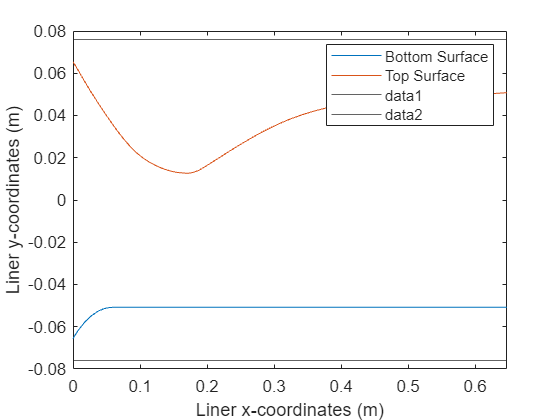


plot(bottomSurface_relative(:,1),bottomSurface_relative(:,2))
hold on
plot(topSurface_relative(:,1),topSurface_relative(:,2))
legend("Bottom Surface", "Top Surface")
xlabel("Liner x-coordinates (m)")
ylabel("Liner y-coordinates (m)")
yline(3*inch2m)
yline(-3*inch2m)
xlim([0 max(topSurface_relative(:,1))])
hold off

## Plotting the variation of the Mach number

To accomplish this, the ratio of the local area to the area at the throat is needed. This ratio shows how the mach number varies through the wind tunnel, as pressure, area and velocity(and by extension mach number) are all related. As pressure increases due to a decrease in area, the velocity of the free stream air must also decrease. With this in mind, we can assume that the velocity - and therefore mach number - is at its lowest when at the throat, and at its highest elsewhere. We can then use this assumption and set the throat as a refenrence point to see how much larger the mach number will be in sections of the wind tunnel with larger areas. In theory, the mach number should not be lower than one, as that would suggest that the throat does not have the smallest area. The  

throatRadius = ( min(topSurface_relative(:,2)) - max(bottomSurface_relative(:,2)) )/2;
throatArea = pi*throatRadius^2

throatArea = 0.0032


localRadius = ( topSurface_relative(:,2) - bottomSurface_relative(:,2) )./2;
localArea = pi*localRadius.^2

localArea =     0.0135
    0.0120
    0.0103
    0.0088
    0.0077
    0.0068
    0.0061
    0.0055
    0.0050
    0.0046


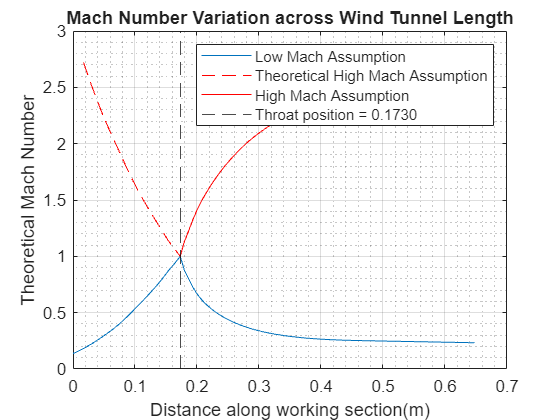


areaRatio = localArea/throatArea;
gamma = 1.4;

% this loop calculates the subsonic theoretical mach numbers of the wind
% tunnel using the newton raphson method
for j = 1:length(areaRatio) % the throat where mach =1  is at position 19
    M(1) = 0.2; % Initial subsonic mach number guess 
    Astar=areaRatio(j);
    for i = 1:1000
        f(i) = Astar.*M(i) - ( ( 1 + ( (gamma - 1)/2 ).*(M(i))^2 )/( (gamma + 1)/2 ) )^( (gamma + 1)/(2*(gamma - 1)) );
        df(i) = Astar - M(i).*( ( 1 + ((gamma - 1)/2).*(M(i))^2 )/( (gamma+1)/2 ) )^( ( (gamma + 1)/(2*(gamma - 1)) )- 1 );
        M_new(j) = M(i) - f(i)./df(i); % Calcuates the new mach number 
        if abs(M_new-M(i)) < 1e-20 % compares the difference in mach number to a specified tolerance 
            break 
        end  
           i=i+1;
           M(i) = M_new(j); % Makes the new mach number the starting point for the next interation 
    end
    j=j+1;
end

% this loop calculates the supersonic theoretical mach numbers of the wind
% tunnel using the newton raphson method
for j = 1:length(areaRatio) % the throat where mach =1  at position 19
    M_super(1) = 1.8; % Initial guess for supersonic mach number 
    Astar=areaRatio(j);
    for i = 1:1000
        f(i) = Astar.*M_super(i) - ( ( 1 + ( (gamma - 1)/2 ).*(M_super(i))^2 )/( (gamma + 1)/2 ) )^( (gamma + 1)/(2*(gamma - 1)) );
        df(i) = Astar - M_super(i).*( ( 1 + ((gamma - 1)/2).*(M_super(i))^2 )/( (gamma+1)/2 ) )^( ( (gamma + 1)/(2*(gamma - 1)) )- 1 );
        M_new_super(j) = M_super(i) - f(i)./df(i); % Calcuates the new mach number 
        if abs(M_new_super-M_super(i)) < 1e-20 % compares the difference in mach number to a specified tolerance 
            break 
        end  
           i=i+1;
           M_super(i) = M_new_super(j); % Makes the new mach number the starting point for the next interation 
    end
    j=j+1;
end

plot(bottomSurface(:,1),M_new)                  % Plotting the subsonic(low mach) numbers
hold on
plot(bottomSurface(3:19,1),M_new_super(3:19),'r--')                         % Plotting the supersonic(high mach) numbers before it intersects with the low mach plot
plot(bottomSurface(19:end,1),M_new_super(19:end),'r-')                      % Plotting the supersonic(high mach) numbers after it intersects with the low mach plot
xline(bottomSurface(19,1),'k--')
xlabel("Distance along working section(m)")
ylabel("Theoretical Mach Number")
title('Mach Number Variation across Wind Tunnel Length')
legend('Low Mach Assumption', 'Theoretical High Mach Assumption', 'High Mach Assumption', 'Throat position = 0.1730')
grid on
grid minor
hold off


% Assembling a table of the supersonic mach numbers against the distance along the working section
distances = (bottomSurface(:,1));
mach_distance_relationship_arr = [distances M_new_super'];
mach_distance_relationship = array2table(mach_distance_relationship_arr)

mach_distance_relationship = 54×2 table
    mach_distance_relationship_arr1    mach_distance_relationship_arr2
    _______________________________    _______________________________

                      0                            0.13716            
               0.007366                             0.1551            
               0.017018                             2.7209            
               0.026797                             2.5634            
               0.036576                             2.4171            
               0.046228                              2.281            
               0.056007                             2.1542            
               0.065786                             2.0357            
               0.075565                             1.9182            
               0.085217                             1.8022            
               0.094996                

## Calculating and plotting temperature and pressure ratios as they vary across the wind tunnel's length


$$\frac{p_0}{p} = \big[ 1 + \frac{\gamma - 1}{2} M^2 \big]^{ \frac{ \gamma }{ \gamma -1 } }

\\

\frac{T_0}{T} =  1 + \frac{\gamma - 1}{2} M^2 $$


% For the high mach assumption
highMachPressureRatio = ( 1 + ( (gamma-1)/2 ).*M_new_super.^2 ).^( gamma/(gamma - 1) )

highMachPressureRatio =     1.0132    1.0169   24.0445   18.8546   15.0153   12.1384    9.9538    8.2721    6.8914    5.7649    4.8553    4.1590    3.6157    3.1779    2.8184    2.5120    2.2450    2.0594    1.8929    2.2115    2.4871    2.8257    3.1710    3.5270    3.8825    4.2287    4.6030    5.1642    5.7416    6.3206    6.9168    7.5039    8.0970    8.6757    9.2464    9.7963   10.3220   10.7987   11.2656   11.6877   12.0843   12.4536   12.8058   13.1036   13.3569   13.6130   13.8225   13.9839   14.1339   14.2596


highMachTemperatureRatio = 1 + ( (gamma-1)/2 ).*M_new_super.^2

highMachTemperatureRatio =     1.0038    1.0048    2.4807    2.3142    2.1685    2.0406    1.9281    1.8288    1.7359    1.6496    1.5706    1.5026    1.4437    1.3914    1.3445    1.3010    1.2599    1.2292    1.2000    1.2545    1.2973    1.3455    1.3906    1.4335    1.4734    1.5098    1.5468    1.5985    1.6477    1.6935    1.7377    1.7786    1.8177    1.8539    1.8880    1.9194    1.9483    1.9736    1.9976    2.0187    2.0380    2.0556    2.0721    2.0857    2.0972    2.1086    2.1178    2.1248    2.1313    2.1367



% For the low mach assumption
lowMachPressureRatio = ( 1 + ( (gamma-1)/2 ).*M_new.^2 ).^( gamma/(gamma - 1) )

lowMachPressureRatio =     1.0132    1.0169    1.0233    1.0320    1.0429    1.0565    1.0732    1.0933    1.1189    1.1512    1.1915    1.2384    1.2926    1.3560    1.4308    1.5223    1.6380    1.7519    1.8929    1.6560    1.5313    1.4290    1.3572    1.3037    1.2634    1.2328    1.2064    1.1758    1.1520    1.1335    1.1183    1.1061    1.0960    1.0876    1.0806    1.0747    1.0698    1.0658    1.0623    1.0594    1.0569    1.0547    1.0527    1.0512    1.0499    1.0487    1.0478    1.0471    1.0464    1.0459


lowMachTemperatureRatio = 1 + ( (gamma-1)/2 ).*M_new.^2

lowMachTemperatureRatio =     1.0038    1.0048    1.0066    1.0090    1.0121    1.0158    1.0204    1.0258    1.0326    1.0410    1.0513    1.0630    1.0761    1.0909    1.1078    1.1276    1.1514    1.1737    1.2000    1.1550    1.1295    1.1074    1.0912    1.0787    1.0691    1.0616    1.0551    1.0474    1.0413    1.0364    1.0325    1.0292    1.0265    1.0243    1.0224    1.0208    1.0195    1.0184    1.0174    1.0166    1.0159    1.0153    1.0148    1.0144    1.0140    1.0137    1.0134    1.0132    1.0130    1.0129


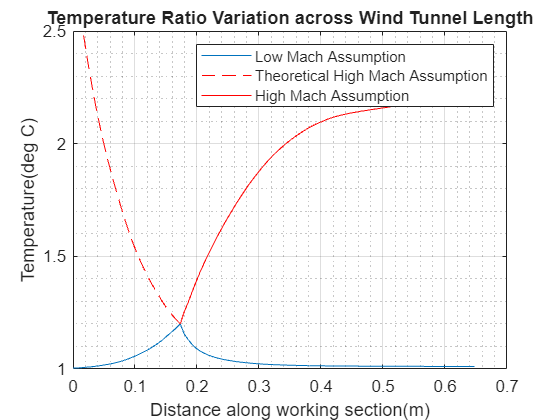


% Plotting the Tempreature Ratio Variation
plot(bottomSurface(:,1),lowMachTemperatureRatio)                  % Plotting the subsonic(low mach) numbers' tempreature ratios
hold on
grid on
grid minor
plot(bottomSurface(3:19,1),highMachTemperatureRatio(3:19),'r--')                         % Plotting the supersonic(high mach) numbers' tempreature ratios before it intersects with the low mach plot
plot(bottomSurface(19:end,1),highMachTemperatureRatio(19:end),'r-')                      % Plotting the supersonic(high mach) numbers' tempreature ratios after it intersects with the low mach plot
xlabel("Distance along working section(m)")
ylabel("Temperature(deg C)")
title('Temperature Ratio Variation across Wind Tunnel Length')
legend('Low Mach Assumption', 'Theoretical High Mach Assumption', 'High Mach Assumption')
hold off

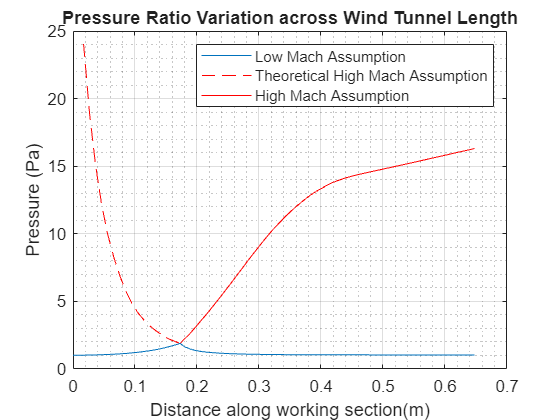


% PLotting the Pressure Ratio Variation
plot(bottomSurface(:,1),lowMachPressureRatio)                  % Plotting the subsonic(low mach) numbers' pressure ratios
hold on
grid on
grid minor
plot(bottomSurface(3:19,1),highMachPressureRatio(3:19),'r--')                         % Plotting the supersonic(high mach) numbers' pressure ratios before it intersects with the low mach plot
plot(bottomSurface(19:end,1),highMachPressureRatio(19:end),'r-')                      % Plotting the supersonic(high mach) numbers' pressure ratios after it intersects with the low mach plot
xlabel("Distance along working section(m)")
ylabel("Pressure (Pa)")
title('Pressure Ratio Variation across Wind Tunnel Length')
legend('Low Mach Assumption', 'Theoretical High Mach Assumption', 'High Mach Assumption')
hold off

# Task 1.2: WT measured pressure ratio and Mach number along working section at two test conditions

The wind tunnel is run at 2 different pressures - 150psi and 75psi- these are the 2 conditions under which the working section is tested. 

### Preparing the raw data

The provided data has been given in text format and cannot easily be converted to a readable spreadsheet. To achieve a usable tabular format, the data will need to be split into individual elements and the reassembeled into a usable table/array. The following will be my attempt at accomplishing this using the knowledge from py4e.

% Loading the data into MATLAB
supersonic150_psi = readlines("Work\WT Data for Further Aerodynamics cw\Supersonic Data\Data\supersonic150Psi.txt");
supersonic75_psi = readlines("Work\WT Data for Further Aerodynamics cw\Supersonic Data\Data\supersonick75Psi.txt");
supersonicUncertaintity = readlines("Work\WT Data for Further Aerodynamics cw\Supersonic Data\Data\Uncertainty.txt")

supersonicUncertaintity = 7×1 string array
    "Observation from experment"
    ""
    "Barometric pressure smallest unit: 10Pa"
    ""
    "VDAS Pressure Tapping smallest unit: 0.001 Bar"
    ""
    "[i.e. the above data are not the uncertainties but precision]"


p_atm = 98910;
%% Supersonic data at 150 psi

    % Creating an array to store the number of elements needed to iterate
    % through the data
    x = 1:numel(supersonic150_psi);
    
    % Defining the new array to be assembled
    supersonic150_PSI = zeros(1,28);
    
    % Removing empty cells
    for i = x
        line = supersonic150_psi(i);                    % store each cell as a separate line of text
        if line.startsWith("        data [Bar] ")       % check if the line starts with desired data
            line.strip("left");                         % remove undesired left spacing
            arr = strsplit(line);                       % split the strings
            arr(1) = [];                                % remove the empty cell on at start of line
            arr(1) = [];
            arr(1) = "Pressure";
            str2double( arr(2:end) );
            supersonic150_PSI = vertcat(supersonic150_PSI,arr);             % concatenate with main array
        elseif line.startsWith("data [Bar]")
            arr = strsplit(line);
            arr(1) = [];
            arr(1) = "Pressure";
            str2double( arr(2:end) );
            supersonic150_PSI = vertcat(supersonic150_PSI,arr);
        elseif line.startsWith("Pressure")                                  % generating the header names
            columnNames = strsplit(line,{':',' '},CollapseDelimiters=true);
            columnNames(1) = [];
            columnNames(1) = [];
            columnNames(1) = "Pressure Tap Number";
        end
    end
    
    supersonic150_PSI_tab = array2table(supersonic150_PSI);
    supersonic150_PSI_tab(1,:) = [];
    
    supersonic150_PSI_tab.Properties.VariableNames = columnNames;

%% Supersonic data at 75 psi


    % Creating an array to store the number of elements needed to iterate
    % through the data
    x = 1:numel(supersonic75_psi);
    
    % Defining the new array to be assembled
    supersonic75_PSI = zeros(1,28);
    
    % Removing empty cells
    for i = x
        line = supersonic75_psi(i);                    % store each cell as a separate line of text
        if line.startsWith("        data [Bar] ")       % check if the line starts with desired data
            line.strip("left");                         % remove undesired left spacing
            arr = strsplit(line);                       % split the strings
            arr(1) = [];                                % remove the empty cell on at start of line
            arr(1) = [];
            arr(1) = "Pressure";
            str2double( arr(2:end) );             % converting the pressures from bar to Pa
            supersonic75_PSI = vertcat(supersonic75_PSI,arr);             % concatenate with main array
        elseif line.startsWith("data [Bar]")
            arr = strsplit(line);
            arr(1) = [];
            arr(1) = "Pressure";
            str2double( arr(2:end) );
            supersonic75_PSI = vertcat(supersonic75_PSI,arr);
        elseif line.startsWith("Pressure")                                  % generating the header names
            columnNames = strsplit(line,{':',' '},CollapseDelimiters=true);
            columnNames(1) = [];
            columnNames(1) = [];
            columnNames(1) = "Pressure Tap Number";
        end
    end
    
    supersonic75_PSI_tab = array2table(supersonic75_PSI);
    supersonic75_PSI_tab(1,:) = [];
    
    supersonic75_PSI_tab.Properties.VariableNames = columnNames;

%% Converting from bar to Pa

    supersonic75_PSI_array = str2double( table2array( supersonic75_PSI_tab(:,2:end-1) ) );
    supersonic75_PSI_pascals_array = p_atm + supersonic75_PSI_array(:,2:26).*bar2Pa + 269;              % Absolute pressure at 75 psi working condition
    supersonic75_PSI_ave = mean(supersonic75_PSI_pascals_array);

    supersonic150_PSI_array = str2double( table2array( supersonic150_PSI_tab(:,2:end-1) ) );
    supersonic150_PSI_pascals_array = p_atm + supersonic150_PSI_array*bar2Pa + 269;                     % Absolute pressure at 150 psi working condition
    supersonic150_PSI_ave = mean(supersonic150_PSI_pascals_array);

    % Assembling tables of the converted values
    supersonic150_PSI_pascals_tab = [supersonic150_PSI_tab(:,1)];
    supersonic150_PSI_pascals_tab = horzcat( supersonic150_PSI_pascals_tab,array2table(supersonic150_PSI_pascals_array) );
    % supersonic150_PSI_pascals_tab.Properties.VariableNames = columnNames

    supersonic75_PSI_pascals_tab = [supersonic75_PSI_tab(:,1)];
    supersonic75_PSI_pascals_tab = horzcat( supersonic75_PSI_pascals_tab,array2table(supersonic75_PSI_pascals_array) );
    % supersonic75_PSI_pascals_tab.Properties.VariableNames = columnNames

%% Finding the pressure ratios (P_0/P)
% For the 150psi working condition
pressureRatio_150_plot = [ supersonic150_PSI_ave(:,1)./supersonic150_PSI_ave(:,1) supersonic150_PSI_ave(:,1)./supersonic150_PSI_ave(:,2:26) ];
windTunnelLength150 = linspace(0,bottomSurface(end,1),numel(pressureRatio_150_plot))                                                                                             % the pressure tap numbers

windTunnelLength150 =          0    0.0259    0.0518    0.0777    0.1036    0.1295    0.1554    0.1814    0.2073    0.2332    0.2591    0.2850    0.3109    0.3368    0.3627    0.3886    0.4145    0.4404    0.4663    0.4923    0.5182    0.5441    0.5700    0.5959    0.6218    0.6477


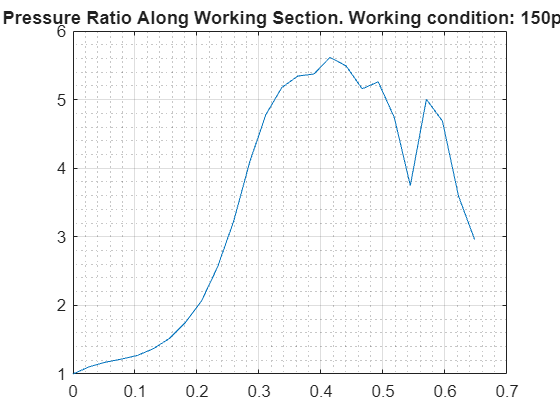

plot(windTunnelLength150,pressureRatio_150_plot')
grid on
grid minor
title('Pressure Ratio Along Working Section. Working condition: 150psi')

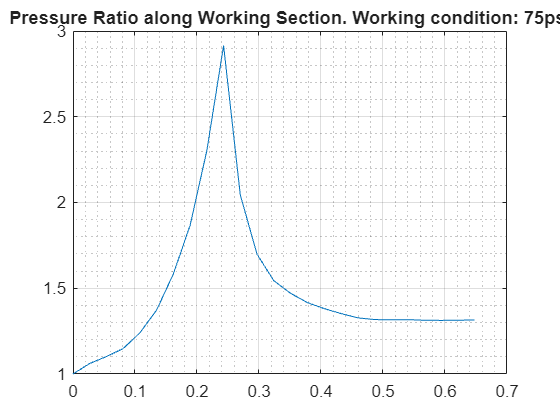




% % For the 75psi working condition
pressureRatio_75_plot = [ supersonic75_PSI_ave(:,1)./supersonic75_PSI_ave(:,1) supersonic75_PSI_ave(:,1)./supersonic75_PSI_ave(:,2:25) ];
windTunnelLength75 = linspace(0,bottomSurface(end,1),numel(pressureRatio_75_plot));                                                                                             % the pressure tap numbers
plot(windTunnelLength75,pressureRatio_75_plot')
grid on
grid minor
title('Pressure Ratio along Working Section. Working condition: 75psi')

## Finding the mach numbers using the presure ratios


$$\frac{p_0}{p} = \big[ 1 + \frac{\gamma - 1}{2} M^2 \big]^{ \frac{ \gamma }{ \gamma -1 } }

\\

M = \sqrt{ \frac{ \bigg[ \bigg( \frac{p_0}{p} \bigg)^{ \frac{ \gamma -1 }{ \gamma } } - 1 \bigg] }{ \frac{ \gamma - 1 }{2} } } $$



% For the 150psi working condition
mach_150_plot = pressureRatio_150_plot.^0.2857

mach_150_plot =     1.0000    1.0288    1.0461    1.0577    1.0706    1.0938    1.1268    1.1737    1.2302    1.3081    1.3974    1.4953    1.5634    1.5996    1.6141    1.6166    1.6372    1.6268    1.5979    1.6068    1.5599    1.4584    1.5842    1.5549    1.4413    1.3637



% For the 75psi working condition
mach_75_plot = sqrt( 2*( (pressureRatio_75_plot).^( (gamma - 1)/gamma ) - 1 )/(gamma-1) )

mach_75_plot =          0    0.2932    0.3749    0.4490    0.5634    0.6886    0.8380    0.9883    1.1602    1.3371    1.0642    0.9037    0.8130    0.7632    0.7234    0.6956    0.6716    0.6496    0.6401    0.6387    0.6394    0.6365    0.6357    0.6369    0.6374


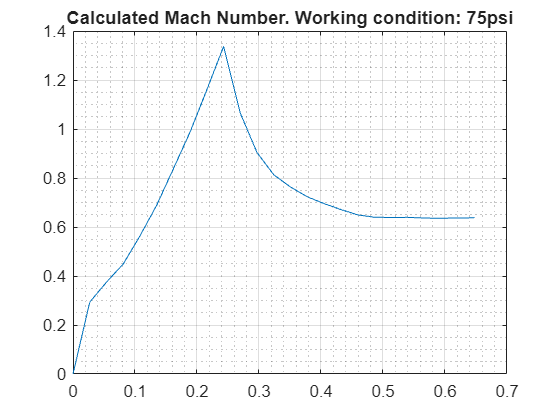


% Plotting the mach numbers
plot(windTunnelLength75,mach_75_plot)
grid on
grid minor
title("Calculated Mach Number. Working condition: 75psi")

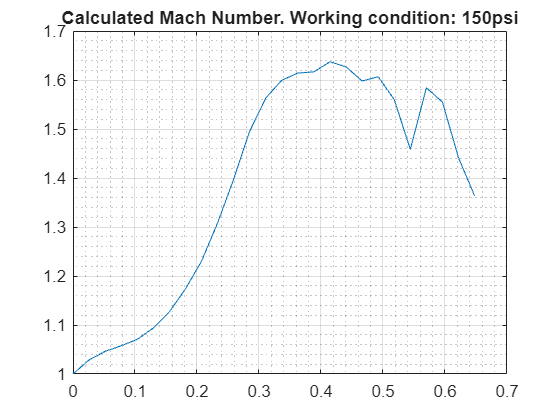

plot(windTunnelLength150,mach_150_plot)
grid on
grid minor
title("Calculated Mach Number. Working condition: 150psi")

## Finding the temperature ratios using pressure ratios


$$\frac{T_0}{T} = 1 + \frac{(\gamma-1)}{2}M^^2$$


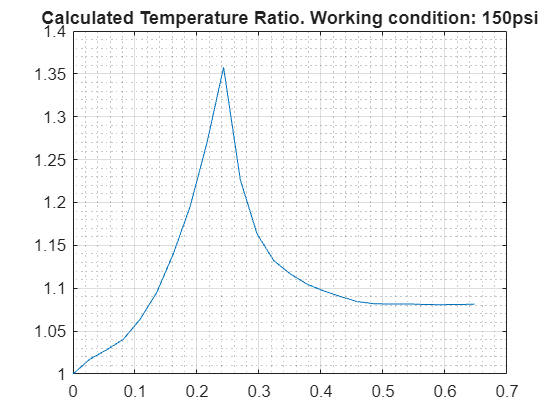

temperarureRatio_75 = 1 + ( (gamma-1)/2 ).* mach_75_plot.^2;
temperarureRatio_150 = 1 + ( (gamma-1)/2 ).* mach_150_plot.^2;

% Plotting the tempreature ratios
plot(windTunnelLength75,temperarureRatio_75)
grid on
grid minor
title("Calculated Temperature Ratio. Working condition: 150psi")

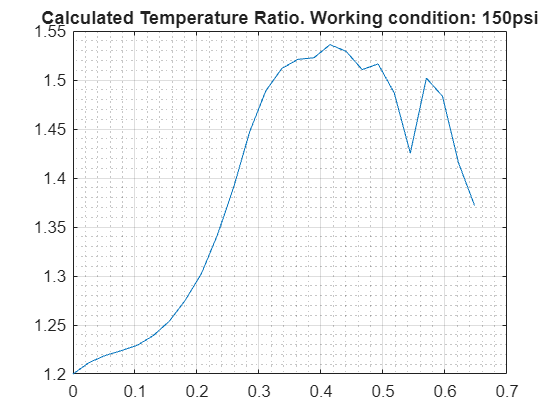


plot(windTunnelLength150,temperarureRatio_150)
grid on
grid minor
title("Calculated Temperature Ratio. Working condition: 150psi")

# Task 1.3: Theoretical Mach number at different regimes, shock and expansion fan angles compared with WT measurements

## Theoretical Mach Numbers

To find the theoretical mach number, the Newton-Raphson method will be used. Following the guidance provided on blackboard, the area ratio and a relationship derived from that formula can be used to 'predict' the mach number

#### Finding M1

I will assume that the centre of the wedge is at the centre of the working section. From this, the x-coordiante of the wedge LE can be found and the theoretical mach number at this point(if there was no wedge inside the working section) can be calculated. This value is M1

wedgeSpan = 25.3;                       % the length of the wedge in [mm]
wedgeThickness = 2.22;                  % the thickness of the wedge measured from the bottommost point to the topmost point
workSectionDistance = 19;               % distance of the working section's centre from the inlet of the wind tunnel. In [in.]

wedgeLE = (workSectionDistance*inch2m) - (wedgeSpan*10^-3)/2;           % the x-coordinate along the wind tunnel for the wedge L.E.

mach_distance_relationship;

% Finding M1 at the wedge L.E using "mach_distance_relationship"
M1 = interp1(mach_distance_relationship_arr(:,1),mach_distance_relationship_arr(:,2),wedgeLE,"linear")

M1 = 2.3940


% Finding M2
firstNormalAngle = atand((wedgeThickness/2)/(wedgeSpan/2));
firstObliqueShockAngle = 40;                                                         % Measured from image
M_n1 = M1*sind(firstObliqueShockAngle)

M_n1 = 1.5388

M_n2_squared = sqrt(( (gamma - 1)*M_n1^2 + 2 )/( 2.*gamma*M_n1.^2 - (gamma - 1) ) );
M2 = ( sqrt(M_n2_squared) )/( sind(firstObliqueShockAngle - firstNormalAngle) )

M2 = 1.4464


% Finding M3 using Prandtl-Meyer
prandtlM2 = sqrt( (gamma + 1)/(gamma - 1) )*atand( sqrt( ( (gamma - 1)/(gamma + 1) )*(M2^2 - 1) ) ) - atand( sqrt(M2^2 - 1) );
prandtlM3 = 2*firstNormalAngle + prandtlM2;
M3 = 1.445                                                       % Read from table using prandtlM3 value

M3 = 1.4450


% Finding M4
warning("Update the value for 'secondObliqueShockAngle' and remove this warning. The curreent value is just a guess")

secondObliqueShockAngle = 36;
M_n3 = M3*sind(secondObliqueShockAngle)

M_n3 = 0.8493

M_n3_squared = sqrt(( (gamma - 1)*M_n3^2 + 2 )/( 2.*gamma*M_n3.^2 - (gamma - 1) ) );
M4 = ( sqrt(M_n3_squared) )/( sind(firstObliqueShockAngle - firstNormalAngle) )

M4 = 1.9015

### Plotting the flow over the wedge

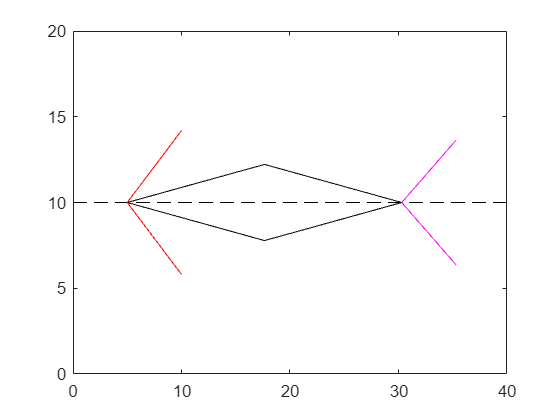

plot([0 40],[10 10],'k--')                            % A horizontal line
hold on
% Plotting the wedge shape
plot([5 5+wedgeSpan/2 5+wedgeSpan],[10 10+wedgeThickness 10],'k-')                      % Upper Surface
plot([5 5+wedgeSpan/2 5+wedgeSpan],[10 10-wedgeThickness 10],'k-')                      % Lower Surface
ylim([0 20])

% Plotting the oblique shocks due to M1's deflection
M1_x_dist = 5;                                                                      % I decided that the visual representation of the shock formed after M1 makes contact with the wedge will end after 5 horizontal units along the plotted wedge. This distance will be used to find the vertical unit distance usig the oblique shock angle
M1_y_dist = M1_x_dist*tand(firstObliqueShockAngle);
plot([5 5+M1_x_dist],[10 10+M1_y_dist],'r-')
plot([5 5+M1_x_dist],[10 10-M1_y_dist],'r-')

% Plotting the expansion fan(s) at the transition from M2 to M3


% Plotting the shock at the end of the wedge
M4_x_dist = 5;
M4_y_dist = M4_x_dist*tand(secondObliqueShockAngle);
plot([5+wedgeSpan 5+wedgeSpan+M1_x_dist],[10 10+M4_y_dist],'m-')
plot([5+wedgeSpan 5+wedgeSpan+M1_x_dist],[10 10-M4_y_dist],'m-')
hold off

## Experimental Mach Numbers

The core method here is the same as the moethod used to find the theoretical ach numbers. The only difference is that the data set used to interpolate the mach numbers has changed from the calculated values in task 1.1 to the values from task 1.2 where the experimental pressure rations were used to calulate the mach numbers

% Finding M1 using the experimental mach numbers data set
mach_distance_relationship_experimental_arr = [windTunnelLength150' mach_150_plot'];
mach_distance_relationship_experimental = array2table(mach_distance_relationship_arr);
M1_experiment = interp1(mach_distance_relationship_experimental_arr(:,1),mach_distance_relationship_experimental_arr(:,2),wedgeLE,"linear")

M1_experiment = 1.5991


% Finding M2
firstObliqueShockAngle_experiment = 45;                                                         % Read from 'Oblique Shock Angle Chart (NACA Report 1135)'. Using M1 value
M_n1 = M1*sind(firstObliqueShockAngle_experiment)

M_n1 = 1.6928

M_n2_squared_experimental = sqrt(( (gamma - 1)*M_n1^2 + 2 )/( 2.*gamma*M_n1.^2 - (gamma - 1) ) );
M2_experiment = ( sqrt(M_n2_squared_experimental) )/( sind(firstObliqueShockAngle_experiment - firstNormalAngle) )

M2_experiment = 1.2473


% Finding M3 using Prandtl-Meyer
prandtlM2_experiment = sqrt( (gamma + 1)/(gamma - 1) )*atand( sqrt( ( (gamma - 1)/(gamma + 1) )*(M2^2 - 1) ) ) - atand( sqrt(M2^2 - 1) );
prandtlM3_experiment = 2*firstNormalAngle + prandtlM2_experiment;
M3_experiment = 1.785                                                       % Read from table using prandtlM3_experiment value

M3_experiment = 1.7850


% Finding M4
secondObliqueShockAngle_experiment = 38;                            % Read from 'Oblique Shock Angle Chart (NACA Report 1135)'. Using M3 value
M_n3_experiment = M3_experiment*sind(secondObliqueShockAngle_experiment)

M_n3_experiment = 1.0990

M_n3_squared_experiment = sqrt(( (gamma - 1)*M_n3_experiment^2 + 2 )/( 2.*gamma*M_n3_experiment.^2 - (gamma - 1) ) );
M4_experiment = ( sqrt(M_n3_squared_experiment) )/( sind(firstObliqueShockAngle_experiment - firstNormalAngle) )

M4_experiment = 1.4866

### Plotting the flow over the wedge

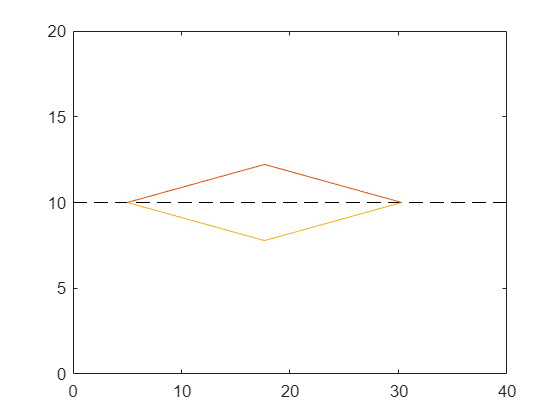

plot([0 40],[10 10],'k--')                            % A horizontal line
hold on
% Plotting the wedge shape
plot([5 5+wedgeSpan/2 5+wedgeSpan],[10 10+wedgeThickness 10])                      % Upper Surface
plot([5 5+wedgeSpan/2 5+wedgeSpan],[10 10-wedgeThickness 10])                      % Lower Surface
ylim([0 20])
hold off

# Task 1.4 Comparison of theory and WT measurements along working section (Mach  number, pressure ratio, temperature ratio)

## Mach Number Comparison

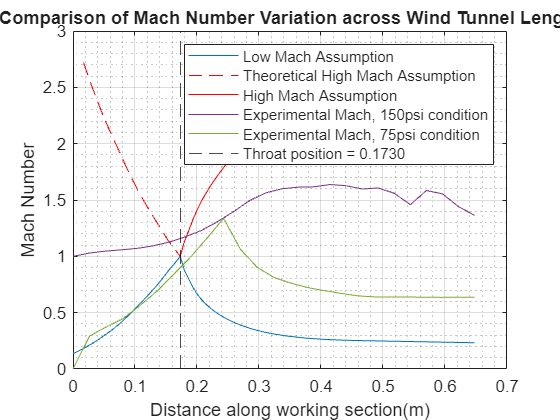

% For the theoretical mach numbers
plot(bottomSurface(:,1),M_new)                  % Plotting the subsonic(low mach) numbers
hold on
plot(bottomSurface(3:19,1),M_new_super(3:19),'r--')                         % Plotting the supersonic(high mach) numbers before it intersects with the low mach plot
plot(bottomSurface(19:end,1),M_new_super(19:end),'r-')                      % Plotting the supersonic(high mach) numbers after it intersects with the low mach plot
xline(bottomSurface(19,1),'k--')

% For the experimental mach numbers
plot(windTunnelLength150,mach_150_plot)                          % 150psi condition
plot(windTunnelLength75,mach_75_plot)                            % 75psi condition

xlabel("Distance along working section(m)")
ylabel("Mach Number")
title('Comparison of Mach Number Variation across Wind Tunnel Length')
legend('Low Mach Assumption', 'Theoretical High Mach Assumption', 'High Mach Assumption', 'Throat position = 0.1730', 'Experimental Mach, 150psi condition', 'Experimental Mach, 75psi condition')
grid on
grid minor
hold off

## Pressure Ratio Comparison

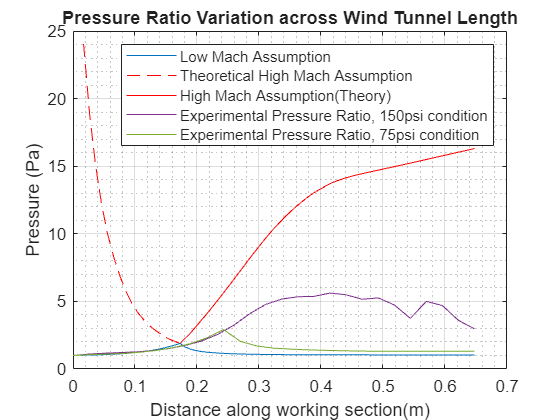

% For the theoretical pressure ratios
plot(bottomSurface(:,1),lowMachPressureRatio)                  % Plotting the subsonic(low mach) numbers' pressure ratios
hold on
plot(bottomSurface(3:19,1),highMachPressureRatio(3:19),'r--')                         % Plotting the supersonic(high mach) numbers' pressure ratios before it intersects with the low mach plot
plot(bottomSurface(19:end,1),highMachPressureRatio(19:end),'r-')                      % Plotting the supersonic(high mach) numbers' pressure ratios after it intersects with the low mach plot


% For the experimental pressure ratios
plot(windTunnelLength150,pressureRatio_150_plot')
plot(windTunnelLength75,pressureRatio_75_plot')

grid on
grid minor
xlabel("Distance along working section(m)")
ylabel("Pressure (Pa)")
title('Pressure Ratio Variation across Wind Tunnel Length')
legend('Low Mach Assumption', 'Theoretical High Mach Assumption', 'High Mach Assumption(Theory)', 'Experimental Pressure Ratio, 150psi condition', 'Experimental Pressure Ratio, 75psi condition')
hold off

## Temperature Ratio Comaprison

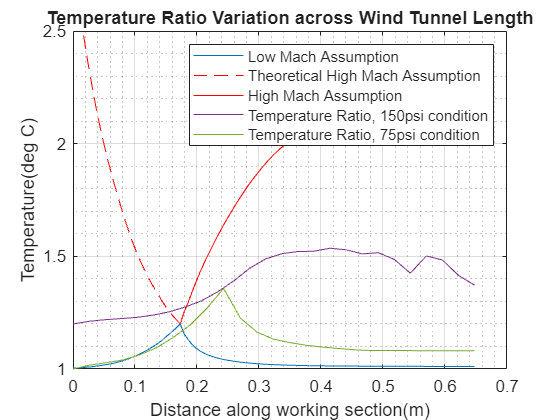

% For the theoretical temperature ratios
plot(bottomSurface(:,1),lowMachTemperatureRatio)                  % Plotting the subsonic(low mach) numbers' tempreature ratios
hold on
plot(bottomSurface(3:19,1),highMachTemperatureRatio(3:19),'r--')                         % Plotting the supersonic(high mach) numbers' tempreature ratios before it intersects with the low mach plot
plot(bottomSurface(19:end,1),highMachTemperatureRatio(19:end),'r-')                      % Plotting the supersonic(high mach) numbers' tempreature ratios after it intersects with the low mach plot

% For the experimental temperature ratios
plot(windTunnelLength150,temperarureRatio_150)
plot(windTunnelLength75,temperarureRatio_75)

grid on
grid minor
xlabel("Distance along working section(m)")
ylabel("Temperature(deg C)")
title('Temperature Ratio Variation across Wind Tunnel Length')
legend('Low Mach Assumption', 'Theoretical High Mach Assumption', 'High Mach Assumption', 'Temperature Ratio, 150psi condition', 'Temperature Ratio, 75psi condition')
hold off